# script for Mechanical analysis

by F Cenni 23 Apr 2020, [francesco.cenni@gmail.com](mailto:francesco.cenni@gmail.com) and P Valadao

*description*** extract mechanical parameters (ankle range of motion, torque) during slow passive stretch. EMG is used to check when is truly passive

*infos*** - graphs with 2SD lines in the EMG graphs to spot FP/FN ---> REMEMBER !!!break point @399 (close all) <-- - check 'var' tags to understand the variables - min torque WITHIN stretch interval used for normalization (passive torque and energy)

*parameters*** - t1=30;==> time in s between the stretches knee extended and flexed - threshold_heel = 5; - define setup1(=PF angle of 47.4 deg) or setup2(=PF angle of 35.4 deg) info: between August to November 2019, the pin that physically stopped the plantarflexion movement at 35.4 degrees was changed, resulting in a new PF angle of 47.4 deg.

PV: data trimming section, changed the emg signal on pre-plots to filt. Changed results output, changed char to string on 236/238/252

New version PV (07/04/22): Created analysis pipeline for total peak torque.

clc
clear all
close all

## !!!choose setup!!!

typeSETUP = char('setup2'); %or 'setup2' as explained above

## Input and Load Data (smr files)

%path and filename of the data stored
dataPath = 'C:\Doutorado\Matlab\Paper II\Mechanics\Flex_smr\';
fileName = '5106_pre1_Flex.smr';
data = ImportSMR([dataPath fileName]);
Subject = string(fileName(1:4));
Group = "TD";
Test = "Pre1";

%Data Trimming 
% data(1).imp.adc = data(1).imp.adc(1:140000);
% data(2).imp.adc = data(2).imp.adc(1:140000);
% data(3).imp.adc = data(3).imp.adc(1:140000);
% data(4).imp.adc = data(4).imp.adc(1:140000);
% data(7).imp.adc = data(7).imp.adc(1:140000);
% data(8).imp.adc = data(8).imp.adc(1:14000);

## channel_1:Torque data [Nm]

information extracted from the struct

f_sample_ch1=1/(data(1).hdr.adc.SampleInterval(1)*data(1).hdr.adc.SampleInterval(2)); %sample frequency
variable_name_ch1=data(1).hdr.title;  %name of the variable
scale_factor_ch1=data(1).hdr.adc.Scale; %scaling factor for channel1
unit_ch1=data(1).hdr.adc.Units; %unit channel1
channel1=data(1).imp.adc; % signal (format:int16)
N_samples_ch1=length(channel1); %number of samples
channel1_scaled=(double(channel1))*scale_factor_ch1; %scaling
time = N_samples_ch1/f_sample_ch1; %s
fprintf('the measurements took %d s\n',time); % based on freq of channel1

the measurements took 2.511350e+02 s


%filter the data in channel1 (torque)
% option1
% [b,a]=butter(6,40/(f_sample_ch1/2),'low'); %-->low-pass filter, order=6, cutoff freq= 40Hz
% channel1_scaled_filt = filtfilt(b,a,channel1_scaled); %signal filtered
% option 2 !where each mean is calculated over a sliding window!
channel1_scaled_window = movmean(channel1_scaled,20); % to remove peak-outliers 
% offset detection
starting_value_torque=mean(channel1_scaled_window([1:200])); %average from first 200 samples (arbitrarily chosen)
% offset removed for the torque data (after moving window processing)
torque_data = channel1_scaled_window - starting_value_torque;

## channel_2 (Angle)

information extracted from the struct

f_sample_ch2 = 1/(data(2).hdr.adc.SampleInterval(1)*data(2).hdr.adc.SampleInterval(2));
variable_name_ch2=data(2).hdr.title;  
scale_factor_ch2=data(2).hdr.adc.Scale;
unit_ch2=data(2).hdr.adc.Units; %unit channel2
channel2=data(2).imp.adc;  
N_samples_ch2=length(channel2);
channel2_scaled_int=channel2*scale_factor_ch2;
channel2_scaled_d=(double(channel2))*scale_factor_ch2;% double format
channel2_scaled_int = int8(medfilt1(double(channel2_scaled_int),500)); %further clean the signal, applies a third-order one-dimensional median filter to the input vector, x

## --> DETECTING the EVENTS from the angle signal

%indices
i=1;
%***** for events ev5 --> maxplantar ***
for c = 500:N_samples_ch2
     if c == N_samples_ch2-1 % to avoid to exceed the N_samples_ch2 array for condition with c+1
         break
     end
    % this condition means: the angle data (using offset) should be above
    % 10deg, and the angle data should be constant for a while (N samples = 400)
    if channel2_scaled_int(c) > 10 && channel2_scaled_int(c-400) == channel2_scaled_int(c);
        %this condition means that the angle data start to decrease
        if channel2_scaled_int(c+1) < channel2_scaled_int(c);
            %!!!ankle is started to be dorsiflexed!!!, from full plantarflexion    
            index_ev5(i)=c; %in samples
            maxplantar_ev5(i)=channel2_scaled_d(c); %angle_data_d ,the corresponding angle at index_ev5
            i=i+1;
        end
    end
end

i=1;
%***** for events ev6 --> maxdorsi ****
for d = 1:length(index_ev5) %from ev5, find also ev6 (at max dorsiflexion) 
    if d < length(index_ev5) % to avoid to exceed the index_ev5 array
        [maxdorsi_ev6(i) index(i)]= min(channel2_scaled_d(index_ev5(d):index_ev5(d+1))); %angle_data_d %angle and the corresponding time (in samples)
        index_ev6(i) = index(i)+index_ev5(d); %every events has an offset (index_ev5)
        i=i+1;
    else
        % different condition for the last event
        [maxdorsi_ev6(i) index(i)] = min(channel2_scaled_d(index_ev5(d):N_samples_ch2));%angle_data_d
        index_ev6(i) = index(i)+index_ev5(d);
        i=i+1;
    end
end

%further refine the events (false positive for small range of motion, smaller than 2 deg)
%set as zero the wrong events
for d = 1:length(index_ev5)-1
    if maxplantar_ev5(d+1) - maxdorsi_ev6(d) < 2
        index_ev5(d+1) = 0; 
        maxplantar_ev5(d+1)=0;
        index_ev6(d) = 0;
        maxdorsi_ev6(d) =0;
    end 
end

% and remove the one equal to 0
m=1;n=1;
for i=1:length(maxplantar_ev5)
    if maxplantar_ev5(i) ~= 0
        maxplantar(m)= maxplantar_ev5(i);
        index_ev5a(m)=index_ev5(i);
        m=m+1;
    end
    if maxdorsi_ev6(i) ~= 0
        maxdorsi(n)= maxdorsi_ev6(i);  
        index_ev6a(n)=index_ev6(i);
        n=n+1;
    end
end
range_of_motion = abs(maxplantar - maxdorsi); %total ranges of motion without conditions on EMG/heel raise

% !for ROMs, only those with at least 20deg are kept!
g=1;
for i=1:length(range_of_motion)
    if range_of_motion(i) > 20 
        maxplantarf(g)=maxplantar(i); %f--> final
        maxdorsif(g)=maxdorsi(i);
        index_ev6f(g)=index_ev6a(i);
        index_ev5f(g)=index_ev5a(i);
        g=g+1;
    end
end
%f--> final
range_of_motion_f = abs(maxplantarf - maxdorsif); %total ranges of motion without conditions on EMG/heel raise

ii=1; 
ke_n = 1; %var to count the number of knee extended trials
t1=30;% ==> time in s between the stretches knee extended and flexed
% classification for rom when knee is extended/flexed
while index_ev5f(ii+1) < index_ev6f(ii)+ f_sample_ch2*t1 %index_ev5f(ii+1) 
    rom_knee_extended(ii) = range_of_motion_f(ii);
    ii=ii+1;
    last_event_knee_extended = index_ev6f(ii);
    ke_n = ke_n + 1;
    if ii == length(index_ev5f)
        break
    end
end
rom_knee_extended(ii) = range_of_motion_f(ii);
for j=1:length(index_ev5f)-ii
    rom_knee_flexed(j) = range_of_motion_f(j+ii);
end

## condition for defining offset for ANGLE DATA

switch typeSETUP
    case 'setup1'
    offset = 47.4 - maxplantarf(1);
    case 'setup2'
    offset = 35.4 - maxplantarf(1);
end
%5119/5201: utilize maxplantarf(2)
% offset for the angle data (final)
angle_dataf_int = channel2_scaled_int + int8(offset);
angle_dataf_d = channel2_scaled_d + offset;
maxpl = maxplantarf + offset;
maxdo = maxdorsif + offset;

## Dorsi flexion VELOCITIES [deg/sample]

for ii = 1:length(index_ev5f)
    dorsiflex_vel(ii)=(maxpl(ii)-maxdo(ii))/(index_ev5f(ii)-index_ev6f(ii));
end
%convert velocity in deg/s
dorsiflex_vel_c = dorsiflex_vel*f_sample_ch2;

## torque zeroed at each ankle strecth

for ii = 1:length(index_ev5f)
    prestretch_torque_offset_ev5(ii) = mean(torque_data([index_ev5f(ii)-200:index_ev5f(ii)])); %average from the last 200 samples before each stretch
end

## EMG filter parameters

option: low-pass filter (freq=4KHz)

fcuthigh=195; %high cut frequency in Hz
[b1,a1]=butter(6,fcuthigh/(4000/2),'low'); %order=6, %fs=4000 
% option: bandpass
fcutlow=20;   %low cut frequency in Hz
[b0,a0]=butter(6,[fcutlow,fcuthigh]/(4000/2),'bandpass'); %order=6, %fs=4000

## channels avalable for wired system

channel3=data(3).imp.adc; %soleus
channel4=data(4).imp.adc; %MG

## channels avalable for wireless system

if length(data) > 7 %struct-data check
    channel7=data(7).imp.adc; %soleus
    channel8=data(8).imp.adc; %MG
end

## pre-plots and EMG onsets

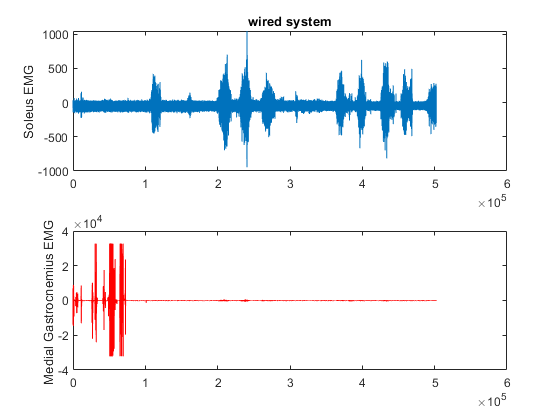

figure(1)
subplot(2,1,1)
plot(channel3)
ylabel('Soleus EMG')
title('wired system')
hold on
subplot(2,1,2)
plot(channel4,'r')
ylabel('Medial Gastrocnemius EMG ')

if length(data) > 7 %struct-data check
    figure(2)
    subplot(2,1,1)
    plot(channel7)
    ylabel('Soleus EMG')
    title('wireless system')
    hold on
    subplot(2,1,2)
    plot(channel8,'r')
    ylabel('Medial Gastrocnemius EMG ')
end

typeEMG = input("Enter type EMG: ",'s');

switch typeEMG
    case "wired"

## ------channel 3 (WIRED channel SOLEUS)

        variable_name_ch3=data(3).hdr.title;  
        scale_factor_ch3=data(3).hdr.adc.Scale; 
        unit_ch3=data(3).hdr.adc.Units; %unit channel3
        channel3=data(3).imp.adc; % signal as int16

## ------channel 4 (WIRED channel MEDIAL GASTROCNEMIUS)

        variable_name_ch4=data(4).hdr.title;  
        scale_factor_ch4=data(4).hdr.adc.Scale; %
        unit_ch4=data(4).hdr.adc.Units; %unit channel4
        channel4=data(4).imp.adc; 
        
    case "wireless"

## ------channel 7 (WIRELESS channel SOLEUS)

        t_delay_ch7 = 200; %ms !!!-->the emg data have a constant delay of 200ms with respect angle data      
        variable_name_ch3=data(7).hdr.title;  
        scale_factor_ch3=data(7).hdr.adc.Scale; 
        unit_ch3=data(7).hdr.adc.Units; %unit 
        channel3=data(7).imp.adc; % signal as int16

## ----channel 8 (wireless channel GASTROCNEMIUS)

        t_delay_ch8 = 200; %ms !!!-->the emg data have a constant delay of 200ms with respect angle data
        variable_name_ch4=data(8).hdr.title;  
        scale_factor_ch4=data(8).hdr.adc.Scale; %
        unit_ch4=data(8).hdr.adc.Units; %unit channel8
        channel4=data(8).imp.adc;         
        
end 
close all 

%ch3        
N_samples_ch3=length(channel3);
channel3_d=double(channel3);
channel3_scaled=channel3_d*scale_factor_ch3; %scaled emg as double
freq_ratio = int8(N_samples_ch3./N_samples_ch2);  
%resampling of the emg signal with respect the one from the angle 
channel3_d2 = resample(channel3_scaled,1,double(freq_ratio)); 
%Use -filtfilt- when it is critical to keep the PHASE information of a signal INTACT
channel3_filt = filtfilt(b1,a1,channel3_d2); %--> signal filtered LOW PASS
channel3_filt2 = filtfilt(b0,a0,channel3_d2); %--> signal filtered BAND PASS
%
p2p_raw = peak2peak(channel3_d2(1:5000));  %peak to peak amplitude of raw signal (5000 samples)
p2p_filt = peak2peak(channel3_filt2(1:5000)); %peak to peak amplitude of filtered signal ; BAND PASS
noise_raw = rms(channel3_d2(1:5000));
noise_filt = rms(channel3_filt2(1:5000));
if p2p_filt > 0.045 || noise_filt > 0.05 %condition on filtered signal
    disp('EMG-SOL high background noise level!')
end

% HERE emg detection is applied
[t3,l]=staude_detectemg(channel3_d2); %channel3_d2 is not filtered!
events_emg_sol=t3{1, 1}; 
%searching onset events 
mm=1;cc=1;
for ii = 1:length(events_emg_sol)
    if events_emg_sol(ii) > index_ev5f(cc) && events_emg_sol(ii) < index_ev6f(cc)%% event within ankle dorsiflexion
        events_emg_sol_sel(cc)=events_emg_sol(ii);
        cc=cc+1;
        mm=mm+1;
        if cc == length(index_ev5f)+1
            break
        end
    elseif index_ev6f(cc) < events_emg_sol(ii) %if no event is found, add a zero
        events_emg_sol_sel(cc)=0;
        cc=cc+1;
        if cc == length(index_ev5f)+1
            break
        end
    end
end
%add zero at the end if needed to match the size with angle events
if events_emg_sol(ii)<index_ev5f(end)
    events_emg_sol_sel = [events_emg_sol_sel, zeros(1,length(index_ev5f) - length(events_emg_sol_sel))];
end
if mm==1 %no event selected
    events_emg_sol_sel=zeros(1,length(index_ev5f));
end

%ch4
N_samples_ch4=length(channel4);
channel4_d=double(channel4);
channel4_scaled=channel4_d*scale_factor_ch4; %scaled emg as double
%resampling of the emg signal with respect the one from the angle 
channel4_d2 = resample(channel4_scaled,1,double(freq_ratio)); %channel4_d
%Use -filtfilt- when it is critical to keep the PHASE information of a signal INTACT
channel4_filt = filtfilt(b1,a1,channel4_d2); %signal filtered LOW PASS
channel4_filt2 = filtfilt(b0,a0,channel4_d2); %signal filtered BAND PASS
%
p2p_raw = peak2peak(channel4_d2(1:5000));  %peak to peak amplitude of raw signal (5000 samples)
p2p_filt = peak2peak(channel4_filt2(1:5000)); %peak to peak amplitude of filtered signal
noise_raw = rms(channel4_d2(1:5000));
noise_filt = rms(channel4_filt2(1:5000));
if p2p_filt > 0.045 || noise_filt > 0.05
    disp('EMG-MG high background noise level!')
end

% HERE emg detection is applied
[t4,l]=staude_detectemg(channel4_d2); %channel3_filt
events_emg_mg=t4{1, 1}; 
%searching onset events 
mm=1;cc=1;
for ii = 1:length(events_emg_mg)
    if events_emg_mg(ii) > index_ev5f(cc) && events_emg_mg(ii) < index_ev6f(cc)%% event within ankle dorsiflexion
        events_emg_mg_sel(cc)=events_emg_mg(ii);
        cc=cc+1;
        mm=mm+1;
        if cc == length(index_ev5f)+1
            break
        end
    elseif index_ev6f(cc) < events_emg_mg(ii) %if no event, add a zero
        events_emg_mg_sel(cc)=0;
        cc=cc+1;
        if cc == length(index_ev5f)+1
            break
        end
    end
end
%
if events_emg_mg(ii)<index_ev5f(end)
    events_emg_mg_sel = [events_emg_mg_sel, zeros(1,length(index_ev5f) - length(events_emg_mg_sel))];
end
if mm==1 %no event selected
    events_emg_mg_sel=zeros(1,length(index_ev5f));
end
%---> calculate mean and std before each stretch (to define thresholds for evaluating emg onsets)
for i = 1:length(index_ev5f)
    mean_emg_interval_plantar_sol(i)=mean(channel3_filt2((index_ev5f(i)-500):index_ev5f(i))); %last 500ms before stretch
    std_emg_interval_plantar_sol(i)=std(channel3_filt2((index_ev5f(i)-500):index_ev5f(i))); %last 500ms before stretch
    mean_emg_interval_plantar_mg(i)=mean(channel4_filt2((index_ev5f(i)-500):index_ev5f(i))); %last 500ms before stretch
    std_emg_interval_plantar_mg(i)=std(channel4_filt2((index_ev5f(i)-500):index_ev5f(i))); %last 500ms before stretch
end

EMG-MG high background noise level!


## new figs! Pre-plots for checking detected events

figure(1), plot(angle_dataf_d), 
sample_v = [1:length(channel3_d2)]';
for ty = 1:length(rom_knee_extended) %loop to create separate figs for each stretch (only in the knee ext condition!)
    fprintf('Stretch number %i.',ty);
    figure(ty+1) 
    subplot(2,1,1) %SOLEUS
    plot(sample_v(index_ev5f(ty)-50:index_ev6f(ty)+50),channel3_filt2(index_ev5f(ty)-50:index_ev6f(ty)+50))
    ylabel('Sol EMG [mV]')
    hold on
    if events_emg_sol_sel(ty) ~= 0
        plot(events_emg_sol_sel(ty),channel3_d2(events_emg_sol_sel(ty)),'ro') %_new        
    end
    plot (index_ev5f(ty),mean(channel3_filt2(index_ev5f(ty)-50:index_ev6f(ty)+50)),'r*')% references of stretch on EMG signal to facilitate checking FN/FP
    plot (index_ev6f(ty),mean(channel3_filt2(index_ev5f(ty)-50:index_ev6f(ty)+50)),'g*')% end of the stretch 
    %new horizontal lines mean+/-2SD based on 500ms before each stretch
    h = yline(mean_emg_interval_plantar_sol(ty)+std_emg_interval_plantar_sol(ty)*2, 'r--');
    h2 = yline(mean_emg_interval_plantar_sol(ty)-std_emg_interval_plantar_sol(ty)*2, 'r--');
    hold off
    subplot(2,1,2) %M. GASTROCNEMIUS
    plot(sample_v(index_ev5f(ty)-50:index_ev6f(ty)+50),channel4_filt2(index_ev5f(ty)-50:index_ev6f(ty)+50))
    ylabel('MG EMG [mV]')
    hold on
    if events_emg_mg_sel(ty) ~= 0
        plot(events_emg_mg_sel(ty),channel4_filt2(events_emg_mg_sel(ty)),'ro') %_new
    end
    plot (index_ev5f(ty),mean(channel4_filt2(index_ev5f(ty)-50:index_ev6f(ty)+50)),'r*')
    plot (index_ev6f(ty),mean(channel4_filt2(index_ev5f(ty)-50:index_ev6f(ty)+50)),'g*')% end of the stretch 
    %new horizontal lines mean+/-2SD based on 500ms before each stretch
    hh = yline(mean_emg_interval_plantar_mg(ty)+std_emg_interval_plantar_mg(ty)*2, 'r--');
    hh2 = yline(mean_emg_interval_plantar_mg(ty)-std_emg_interval_plantar_mg(ty)*2, 'r--');
    hold off
end

Stretch number 1.

Stretch number 2.

Stretch number 3.


close all

## ----channel HEEL DISPLACEMENT (looks like the channel changes, always the last one?)

if length(data) > 7 %struct-data check
    index_heel_disp=10;
else
    index_heel_disp=7;
end
   
variable_name_ch_hd=data(index_heel_disp).hdr.title;  
scale_factor_ch_hd=data(index_heel_disp).hdr.adc.Scale; %
unit_ch_hd=data(index_heel_disp).hdr.adc.Units; %unit channel7
channel_hd=data(index_heel_disp).imp.adc; 
N_samples_ch_hd=length(channel_hd);
channel_hd_d=double(channel_hd);
channel_hd_scaled_bo=channel_hd_d*scale_factor_ch_hd; %bo = before offset
% --> offset detection
t_hd=500; %data 0.5 s, f=1000 Hz
starting_value_hd_scaled=mean(channel_hd_scaled_bo([index_ev5f(1)-t_hd:index_ev5f(1)])); %Heel displacement offset correction using t before the first stretch.
% --> offset removed for the heel displacement data
channel_hd_scaled = channel_hd_scaled_bo - starting_value_hd_scaled;

## overview data available

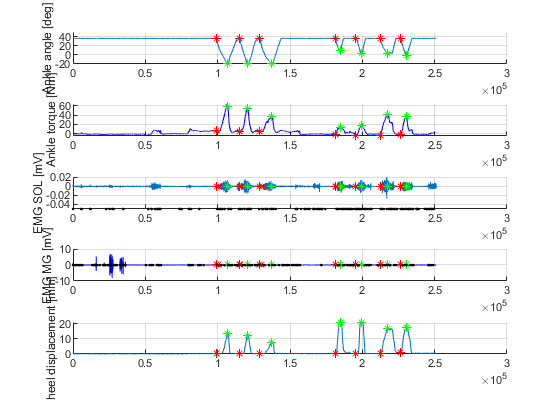

figure(1)
subplot(5,1,1)
hold on
plot(angle_dataf_d) 
plot(index_ev5f,maxpl,'r*')
plot(index_ev6f,maxdo,'g*')
grid on
ylabel('Ankle angle [deg]') 
%
subplot(5,1,2)
hold on
plot(torque_data,'b') 
plot(index_ev5f,torque_data(index_ev5f),'r*')
plot(index_ev6f,torque_data(index_ev6f),'g*')
grid on
ylabel('Ankle torque [Nm]')
%
subplot(5,1,3)
hold on
plot(channel3_filt2) %, channel3_filt2
plot(index_ev5f,0,'r*')
plot(index_ev6f,0,'g*')
plot(events_emg_sol,-0.05,'k.')
plot(events_emg_sol_sel,0,'rx')
grid on
ylabel('EMG SOL [mV]')
%
subplot(5,1,4)
hold on
plot(channel4_filt2,'b') %channel4_filt2
plot(index_ev5f,0,'r*')
plot(index_ev6f,0,'g*')
plot(events_emg_mg,-0.05,'k.')
plot(events_emg_mg_sel,0,'rx')
grid on
ylabel('EMG MG [mV]')
%
subplot(5,1,5)
hold on
plot(channel_hd_scaled)
plot(index_ev5f,channel_hd_scaled(index_ev5f),'r*')
plot(index_ev6f,channel_hd_scaled(index_ev6f),'g*')
ylabel('heel displacement [mm]')
grid on

## condition about heel movements

%threshold 
threshold_heel = 5; %mm
% var initialised as zeros
time_channel_hd_sel = zeros(length(index_ev5f),1);
angle_hd = zeros(length(index_ev5f),1); 
%
for ii = 1:length(index_ev5f)
    for jj = index_ev5f(ii):index_ev6f(ii)
        if channel_hd_scaled(jj) > threshold_heel
            time_channel_hd_sel(ii) = jj; % time (in samples) when the threshold_heel is found
            angle_hd(ii) = angle_dataf_d(jj); %angles that correspond to the threshold_heel
            break
        end
    end
    % if the subjects does not arrive to heel threshold
    if channel_hd_scaled(index_ev6f(ii)) < threshold_heel
        angle_hd(ii) = angle_dataf_d(index_ev6f(ii)); %angles that correspond to maxdo
    end
end

% figure(2)
% subplot(2,1,1)
% plot(angle_dataf_d) 
% hold on
% plot(index_ev5f,maxpl,'r*')
% plot(index_ev6f,maxdo,'g*')
% plot(time_channel_hd_sel,angle_hd,'bo')
% grid on
% legend({'angle','start-stretch','end-stretch','threshold-heel'},'Location','northeast')
% ylabel('Ankle angle [deg]') 
% %
% subplot(2,1,2)
% plot(channel_hd_scaled) 
% hold on
% plot(time_channel_hd_sel,threshold_heel,'bo')
% h = yline(threshold_heel, 'b--');
% grid on
% legend({'heel-displacement','threshold-heel'},'Location','northeast')
% ylabel('heel displacement [mm]')

%-->var1: range of motion (angle) from start movement (maxplantar) till heel displacement (hd) threshold 
range_angle_hd = abs(maxpl - angle_hd');

## condition about torque threshold for slack angle

min value torque within angle stretch ev5-ev6 (from max plnatar to maxdorsi)

time_min_torque_as = zeros(length(index_ev5f),1);
angle_min_torque_as = zeros(length(index_ev5f),1);
for ii = 1:length(index_ev5f)
    [min_torque_as(ii), time_min_torque] = min(torque_data(index_ev5f(ii):index_ev6f(ii)));
    time_min_torque_as(ii) = time_min_torque+index_ev5f(ii); % time (in samples)
    angle_min_torque_as(ii) = angle_dataf_d(time_min_torque+index_ev5f(ii)); % corresponding angle
end
%thresholds 
threshold_torque = 5; %Nm
% 3 cases for PF
threshold_pf5 = 5; %deg
threshold_pf10 = 10; %deg
threshold_pf15 = 15; %deg
% var initialised as zeros
time_channel_torque_sel = zeros(length(index_ev5f),1); 
torque_slack = zeros(length(index_ev5f),1); 
time_torque_threshold_pf5_sel = zeros(length(index_ev5f),1);
time_torque_threshold_pf10_sel = zeros(length(index_ev5f),1); 
time_torque_threshold_pf15_sel = zeros(length(index_ev5f),1); 
torque_threshold_pf5 = zeros(length(index_ev5f),1); 
torque_threshold_pf10 = zeros(length(index_ev5f),1); 
torque_threshold_pf15 = zeros(length(index_ev5f),1); 
%
for ii = 1:length(index_ev5f)
    for jj = index_ev5f(ii):index_ev6f(ii)
        if (angle_dataf_d(jj)<threshold_pf10) && ((torque_data(jj)-min_torque_as(ii))>threshold_torque) % !at least threshold_pf and higher than torque threshold (considering specific offset for the stretch)!
            time_channel_torque_sel(ii) = jj; % time (in samples) when the threshold_torque is found (with pf10!)
            torque_slack(ii) = torque_data(jj) - min_torque_as(ii); 
            break
        end
    end
end
%  at least threshold_pf 5deg (only this condition)
for ii = 1:length(index_ev5f)
    for jj = index_ev5f(ii):index_ev6f(ii)
        if angle_dataf_d(jj) < threshold_pf5 
            time_torque_threshold_pf5_sel(ii) = jj; % time (in samples)
            torque_threshold_pf5(ii) = torque_data(jj) - min_torque_as(ii); 
            break
        end
    end
end
%  at least threshold_pf 10deg (only this condition)
for ii = 1:length(index_ev5f)
    for jj = index_ev5f(ii):index_ev6f(ii)
        if angle_dataf_d(jj) < threshold_pf10 
            time_torque_threshold_pf10_sel(ii) = jj; % time (in samples)
            torque_threshold_pf10(ii) = torque_data(jj) - min_torque_as(ii); 
            break
        end
    end
end
%  at least threshold_pf 15deg (only this condition)
for ii = 1:length(index_ev5f)
    for jj = index_ev5f(ii):index_ev6f(ii)
         if angle_dataf_d(jj) < threshold_pf15 
             time_torque_threshold_pf15_sel(ii) = jj; % time (in samples)
             torque_threshold_pf15(ii) = torque_data(jj) - min_torque_as(ii); 
             break
         end
    end
end

## condition about heel movements and emg onset

==>the first that comes is the event where considered the angle and torque

aa=1;bb=1;cc=1;dd=1;
if typeEMG == "wired"

    for ii = 1:length(index_ev5f)
        % heel displac, emg onsets
        relevant_events_fp = [time_channel_hd_sel(ii) events_emg_sol_sel(ii) events_emg_mg_sel(ii)];
        % integral for calculating passive energy
        %L1
        interv_torque_L1_5 = time_torque_threshold_pf5_sel(ii); 
        interv_torque_L1_10 = time_torque_threshold_pf10_sel(ii); 
        interv_torque_L1_15 = time_torque_threshold_pf15_sel(ii); 
        interv_torque_L1_mintorque = time_min_torque_as(ii);
            
        if max(relevant_events_fp)==0 % all conditions are equal to zero
            events_selected_fp(ii) = 0;
            torque_selected_fp(ii) = torque_data(index_ev6f(ii));
            torque_selected_fp_n(ii) = abs(torque_data(index_ev6f(ii)) - min_torque_as(ii)); 
            angle_selected_fp(ii) = angle_dataf_d(index_ev6f(ii)); 
            range_angle_fp(ii) = abs(angle_dataf_d(index_ev6f(ii)) - angle_dataf_d(index_ev5f(ii)));
           
            torque_interval_5 = torque_data(int32(interv_torque_L1_5):int32(index_ev6f(ii)));
            torque_interval_5_zeroed = torque_interval_5 - min_torque_as(ii); 
            passive_energy_5(ii) = (trapz(torque_interval_5_zeroed))/1000; % /1000 for time conversion (ms-->s)
            torque_interval_10 = torque_data(int32(interv_torque_L1_10):int32(index_ev6f(ii)));
            torque_interval_10_zeroed = torque_interval_10 - min_torque_as(ii); 
            passive_energy_10(ii) = (trapz(torque_interval_10_zeroed))/1000; % /1000 for time conversion (ms-->s)
            torque_interval_15 = torque_data(int32(interv_torque_L1_15):int32(index_ev6f(ii)));
            torque_interval_15_zeroed = torque_interval_15 - min_torque_as(ii); 
            passive_energy_15(ii) = (trapz(torque_interval_15_zeroed))/1000; % /1000 for time conversion (ms-->s)          
            torque_interval_mintorque = torque_data(int32(interv_torque_L1_mintorque):int32(index_ev6f(ii)));
            torque_interval_mintorque_zeroed = torque_interval_mintorque - min_torque_as(ii); % zeroed
            passive_energy_mintorque(ii) = (trapz(torque_interval_mintorque_zeroed))/1000; % /1000 for time conversion (ms-->s)

            range_angle_mintorque(ii) = abs(angle_min_torque_as(ii) - angle_dataf_d(index_ev6f(ii))); 
            
        else
            
            % %fp => fully passive, !min value!
            event_selected_fp = min(relevant_events_fp(relevant_events_fp>0)); 
            events_selected_fp(ii) = event_selected_fp;
            %passive torque at emg onset
            torque_selected_fp(ii) = torque_data(event_selected_fp);
            %passive torque at emg onset NORMALIZED
            torque_selected_fp_n(ii) = abs(torque_selected_fp(ii) - min_torque_as(ii));            
            %angle at emg onset
            angle_selected_fp(ii)= angle_dataf_d(event_selected_fp); 
            %
            range_angle_fp(ii)= abs(angle_dataf_d(event_selected_fp) - angle_dataf_d(index_ev5f(ii)));
        

            range_angle_mintorque(ii)= abs(angle_min_torque_as(ii) - angle_dataf_d(event_selected_fp));
            %L2
            interv_torque_L2 = events_selected_fp(ii); % events emg onset 
            %
            if interv_torque_L1_5 == 0
                passive_energy_5(ii) = 0;
                %aa = aa+1;               
            else
                torque_interval_5 = torque_data(int32(interv_torque_L1_5):int32(interv_torque_L2));
                torque_interval_5_zeroed = torque_interval_5 - min_torque_as(ii); 
                passive_energy_5(ii) = (trapz(torque_interval_5_zeroed))/1000; % /1000 for time conversion (ms-->s)
                %aa = aa+1;
            end
            %
            if interv_torque_L1_10 == 0
                passive_energy_10(ii) = 0;
                %bb = bb+1;  
            else
                torque_interval_10 = torque_data(int32(interv_torque_L1_10):int32(interv_torque_L2));
                torque_interval_10_zeroed = torque_interval_10 - min_torque_as(ii); % zeroed
                passive_energy_10(ii) = (trapz(torque_interval_10_zeroed))/1000; % /1000 for time conversion (ms-->s)
                %bb = bb+1;
            end
            %
            if interv_torque_L1_15 == 0
                passive_energy_15(ii) = 0;
                %cc = cc+1; 
            else
                torque_interval_15 = torque_data(int32(interv_torque_L1_15):int32(interv_torque_L2));
                torque_interval_15_zeroed = torque_interval_15 - min_torque_as(ii); % zeroed
                passive_energy_15(ii) = (trapz(torque_interval_15_zeroed))/1000; % /1000 for time conversion (ms-->s)
                %cc = cc+1;
            end
            %
            if interv_torque_L1_mintorque == 0
                passive_energy_mintorque(ii) = 0;
                %dd = dd+1; 
            else
                torque_interval_mintorque = torque_data(int32(interv_torque_L1_mintorque):int32(interv_torque_L2));
                torque_interval_mintorque_zeroed = torque_interval_mintorque - min_torque_as(ii); % zeroed
                passive_energy_mintorque(ii) = (trapz(torque_interval_mintorque_zeroed))/1000; % /1000 for time conversion (ms-->s)
                %dd = dd+1; 
            end 
        end
    end

else
        
    for ii = 1:length(index_ev5f)
        % heel displac, emg onsets
        relevant_events_fp = [time_channel_hd_sel(ii) events_emg_sol_sel(ii)-t_delay_ch7 events_emg_mg_sel(ii)-t_delay_ch8];
        % integral for calculating passive energy
        %L1
        interv_torque_L1_5 = time_torque_threshold_pf5_sel(ii); 
        interv_torque_L1_10 = time_torque_threshold_pf10_sel(ii); 
        interv_torque_L1_15 = time_torque_threshold_pf15_sel(ii); 
        interv_torque_L1_mintorque = time_min_torque_as(ii);
        
        if max(relevant_events_fp)==0 % all conditions are equal to zero
            events_selected_fp(ii) = 0;
            torque_selected_fp(ii) = torque_data(index_ev6f(ii));
            torque_selected_fp_n(ii) = abs(torque_data(index_ev6f(ii)) - min_torque_as(ii)); 
            angle_selected_fp(ii) = angle_dataf_d(index_ev6f(ii)); 
            range_angle_fp(ii) = abs(angle_dataf_d(index_ev6f(ii)) - angle_dataf_d(index_ev5f(ii)));
           
            torque_interval_5 = torque_data(int32(interv_torque_L1_5):int32(index_ev6f(ii)));
            torque_interval_5_zeroed = torque_interval_5 - min_torque_as(ii); 
            passive_energy_5(ii) = (trapz(torque_interval_5_zeroed))/1000; % /1000 for time conversion (ms-->s)
            torque_interval_10 = torque_data(int32(interv_torque_L1_10):int32(index_ev6f(ii)));
            torque_interval_10_zeroed = torque_interval_10 - min_torque_as(ii); 
            passive_energy_10(ii) = (trapz(torque_interval_10_zeroed))/1000; % /1000 for time conversion (ms-->s)
            torque_interval_15 = torque_data(int32(interv_torque_L1_15):int32(index_ev6f(ii)));
            torque_interval_15_zeroed = torque_interval_15 - min_torque_as(ii); 
            passive_energy_15(ii) = (trapz(torque_interval_15_zeroed))/1000; % /1000 for time conversion (ms-->s)          
            torque_interval_mintorque = torque_data(int32(interv_torque_L1_mintorque):int32(index_ev6f(ii)));
            torque_interval_mintorque_zeroed = torque_interval_mintorque - min_torque_as(ii); % zeroed
            passive_energy_mintorque(ii) = (trapz(torque_interval_mintorque_zeroed))/1000; % /1000 for time conversion (ms-->s)

            range_angle_mintorque(ii) = abs(angle_min_torque_as(ii) - angle_dataf_d(index_ev6f(ii))); 
        else
        
            % fp => fully passive, !min value!
            event_selected_fp = min(relevant_events_fp(relevant_events_fp>0)); 
            events_selected_fp(ii) = event_selected_fp;
            %passive torque at emg onset
            torque_selected_fp(ii) = torque_data(event_selected_fp);
            %passive torque at emg onset NORMALIZED
            torque_selected_fp_n(ii) = torque_selected_fp(ii) - min_torque_as(ii);            
            %angle at emg onset
            angle_selected_fp(ii)= angle_dataf_d(event_selected_fp); 
            %
            range_angle_fp(ii)= abs(angle_dataf_d(event_selected_fp) - angle_dataf_d(index_ev5f(ii)));
        
            % integral for calculating passive energy
            %L1
            interv_torque_L1_5 = time_torque_threshold_pf5_sel(ii); 
            interv_torque_L1_10 = time_torque_threshold_pf10_sel(ii); 
            interv_torque_L1_15 = time_torque_threshold_pf15_sel(ii); 
            interv_torque_L1_mintorque = time_min_torque_as(ii);
            range_angle_mintorque(ii)= abs(angle_min_torque_as(ii) - angle_dataf_d(event_selected_fp));
            %L2
            interv_torque_L2 = events_selected_fp(ii); % events emg onset 
            %
            if interv_torque_L1_5 == 0
                passive_energy_5(ii) = 0;
                %aa = aa+1;               
            else
                torque_interval_5 = torque_data(int32(interv_torque_L1_5):int32(interv_torque_L2));
                torque_interval_5_zeroed = torque_interval_5 - min_torque_as(ii);  % zeroed
                passive_energy_5(ii) = (trapz(torque_interval_5_zeroed))/1000; % /1000 for time conversion (ms-->s)
                %aa = aa+1;
            end
            %
            if interv_torque_L1_10 == 0
                passive_energy_10(ii) = 0;
                %bb = bb+1;  
            else
                torque_interval_10 = torque_data(int32(interv_torque_L1_10):int32(interv_torque_L2));
                torque_interval_10_zeroed = torque_interval_10 - min_torque_as(ii);  % zeroed
                passive_energy_10(ii) = (trapz(torque_interval_10_zeroed))/1000; % /1000 for time conversion (ms-->s)
                %bb = bb+1;
            end
            %
            if interv_torque_L1_15 == 0
                passive_energy_15(ii) = 0;
                %cc = cc+1; 
            else
                torque_interval_15 = torque_data(int32(interv_torque_L1_15):int32(interv_torque_L2));
                torque_interval_15_zeroed = torque_interval_15 - min_torque_as(ii);  % zeroed
                passive_energy_15(ii) = (trapz(torque_interval_15_zeroed))/1000; % /1000 for time conversion (ms-->s)
                %cc = cc+1;
            end
            %
            if interv_torque_L1_mintorque == 0
                passive_energy_mintorque(ii) = 0;
                %dd = dd+1; 
            else
                torque_interval_mintorque = torque_data(int32(interv_torque_L1_mintorque):int32(interv_torque_L2));
                torque_interval_mintorque_zeroed = torque_interval_mintorque - min_torque_as(ii);  % zeroed
                passive_energy_mintorque(ii) = (trapz(torque_interval_mintorque_zeroed))/1000; % /1000 for time conversion (ms-->s)
                %dd = dd+1; 
            end 
        end
    end

end

### Total and common range peak torque

created by PV 15/04/22. cm_pt = highest torque in the common range of motion (16.5-4 deg of PF) minus the trial minimum torque. total_pt = highest torque in the trial minus the minimum torque.

if typeSETUP == "setup1"
   if maxpl > 48 | maxpl < 45
       warning("ROM is incorrect")
   end
elseif typeSETUP == "setup2"
    if maxpl > 37 | maxpl < 34
        warning("ROM is incorrect")
    end
end

angle = round(angle_dataf_d,1);
a = 1;cm_pt = zeros(ke_n,1);cm_pt_loc = zeros(ke_n,1); deg4 = zeros(ke_n,1);
total_pt = zeros(ke_n,1); total_pt_loc = zeros(ke_n,1);
for i = 1:ke_n % go through stretch trials
    if time_channel_hd_sel(i) == 0 %heel did not raise above threshold
      [M,I] = max(torque_data(index_ev5f(i):index_ev6f(i)));
      total_pt(a) = M - min_torque_as(i); %total torque
      total_pt_loc(a) = index_ev5f(i) + I -1;%global sample for total torque
    else %heel raised above 5mm
      [M,I] = max(torque_data(time_min_torque_as(i):time_channel_hd_sel(i)));
      total_pt(a) = M - min_torque_as(i); %total torque
      total_pt_loc(a) = time_min_torque_as(i) + I -1;%global sample for total torque  
    end
    for ii = index_ev5f(i):index_ev6f(i) %go through all datapoints in each stretch
        if angle(ii) == 4 % find sample for end of common rom (4 deg of PF)
            deg4(a) = ii; %global sample
            if ii > time_min_torque_as(i) %end of the common rom is after the artefact 
             [M, I] = max(torque_data(time_min_torque_as(i):ii)); 
             cm_pt(a) = M - min_torque_as(i); % max torque in the common rom minus min torque
             cm_pt_loc(a) = time_min_torque_as(i)+I-1; %global sample for cm pt
             a = a + 1;
            else
             warning("4 deg PF happened before minimum torque in trial %i", i)
             a = a + 1;
            end
        break
        end
    end
end
%total_pt = total_pt(total_pt~=0); %exclude trials with invalid results (artefact longer than end of rom)
%total_pt_loc = total_pt_loc(total_pt_loc ~= 0);

## save relevant variables

var1: range of motion (angle) from start movement (maxplantar) till heel displacement (hd) threshold 

Maximum_ROM = range_angle_hd';
% var2: slack angle when: --> AT LEAST 10deg PF and higher than torque threshold
% var3: passive energy calculations for 5-10-15 deg PF, and using min torque
Passive_energy_5PF = passive_energy_5';
Passive_energy_10PF = passive_energy_10';
Passive_energy_15PF = passive_energy_15';
Passive_energy_0torque = passive_energy_mintorque';
%var4 : value of passive torque that is read at emg onset
%torque_selected_fp_t = torque_selected_fp'; not necessary - without
%correcting the offset there is no way to compare between subjects
%var5: passive torque at emg onset NORMALIZED using min torque at angle-stretch interval
Passive_PT = torque_selected_fp_n'; 
% var6: passive rom till emg onset (and heel displacement)
Passive_ROM = range_angle_fp'; 
% var7: dorsiflexion velocity [deg/s]
Stretch_vel = abs(dorsiflex_vel_c');
% range of motion between torque min and emg onset 
Range_0torque_EMG = range_angle_mintorque';
% passive energy normalized by ankle degree
Passive_energy_0torque_deg = Passive_energy_0torque./Range_0torque_EMG;
%
Subject(1:ke_n,1) = Subject;
Group(1:ke_n,1) = Group;
Test(1:ke_n,1) = Test;
%total peak torque analysis (was done separately later)
Flex_results_2 = table(Subject, Maximum_ROM(1:ke_n),Passive_ROM(1:ke_n), total_pt, cm_pt)

Flex_results_2 = 3×5 table
    Subject          Var2                Var3              total_pt             cm_pt      
    _______    ________________    ________________    ________________    ________________

    "5106"     45.0897216796875         14.74609375    38.0528428952675    11.0228299698792
    "5106"     40.9088134765625     2.5726318359375    29.7604007727932    10.7768677035347
    "5106"        49.8291015625    16.8853759765625    27.9807914339472    6.35368072893471



%initial analysis
% Flex_results = table(Subject, Group, Test, Maximum_ROM,Passive_ROM,Passive_PT, Passive_energy_5PF,Passive_energy_10PF,Passive_energy_15PF,...
%     Passive_energy_0torque, Stretch_vel,Range_0torque_EMG,Passive_energy_0torque_deg)

## figures

figure(4) plot(channel3_d2,'r') hold on %plot(channel3_filt,'g') plot(channel3_filt2,'b') %ylim([-0.3 0.3]) grid on legend({'raw','bandpass'},'Location','northwest') ylabel('EMG SOL [mV]') xlabel('time [samples]') % figure(5) plot(channel4_d2,'r') hold on % plot(channel4_filt,'g') plot(channel4_filt2,'b') %ylim([-0.3 0.3]) %legend({'raw','filter','bandpass'},'Location','northwest') legend({'raw','bandpass'},'Location','northwest') grid on ylabel('EMG MG [mV]') xlabel('time [samples]')

% figure(6)
% subplot(2,1,1)
% hold on
% plot(angle_dataf_d) 
% plot(index_ev5f,maxpl,'r*')
% plot(index_ev6f,maxdo,'g*')
% for ty = 1:length(index_ev5f)
%     if events_emg_sol_sel(ty) ~= 0
%         plot(events_emg_sol_sel(ty),angle_dataf_d(events_emg_sol_sel(ty)),'ks')
%     end
%     if time_channel_hd_sel(ty) ~= 0
%         plot(time_channel_hd_sel(ty),angle_dataf_d(time_channel_hd_sel(ty)),'k*')
%     end
% end
% grid on
% legend({'angle','start-stretch','onset-emg-sol','onset-emg-mg','threshold-heel'},'Location','northeast')
% ylabel('Ankle angle [deg]') 
%
% subplot(5,1,2)
% plot(torque_data,'b') %signal obtained after moving win
% hold on
% %plot(channel1_scaled_filt-starting_value_torque,'g') %signal filtered
% plot(index_ev5f,0,'r.')
% plot(index_ev6f,0,'g.')
% grid on
% ylabel('Ankle torque [Nm]')
%
% subplot(5,1,3)
% hold on
% plot(channel3_filt2) %channel3_d
% plot(index_ev5f,0,'r.')
% plot(index_ev6f,0,'g.')
% plot(events_emg_sol_sel,0,'ks')
% %plot(events_emg_sol,0,'k.')
% %ylim([-0.3 0.3])
% grid on
% ylabel('EMG SOL [mV]')
% %
% subplot(5,1,4)
% hold on
% plot(channel4_filt2,'b')
% plot(index_ev5f,0,'r.')
% plot(index_ev6f,0,'g.')
% plot(events_emg_mg_sel,0,'kx')
% %plot(events_emg_mg,0,'k.')
% %ylim([0 0.1])
% grid on
% ylabel('EMG MG [mV]')
%
% subplot(2,1,2)
% hold on
% plot(channel_hd_scaled)
% plot(index_ev5f,channel_hd_scaled(index_ev5f),'r*')
% plot(index_ev6f,channel_hd_scaled(index_ev6f),'g*')
% plot(time_channel_hd_sel,threshold_heel,'k*')
% ylabel('heel displacement [mm]')
% legend({'heel-displacement','start-stretch','end-stretch','threshold-heel'},'Location','northeast')
% grid on


Total torque (red diamonds) stays above torque data because it is already corrected by the minimum torque.

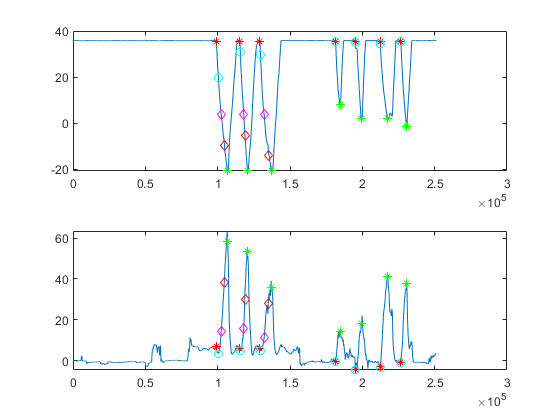

figure(6)
subplot(2,1,1)
plot(angle)
hold on
plot(index_ev5f,maxpl,'r*')%start of the stretch
plot(index_ev6f,maxdo,'g*')%end of the stretch
plot(time_min_torque_as,angle(time_min_torque_as),'co')%minimum torque in trial
plot(cm_pt_loc(cm_pt_loc ~= 0),angle(cm_pt_loc(cm_pt_loc~=0)),'md')%max common range torque
plot(total_pt_loc(total_pt_loc~=0), angle(total_pt_loc(total_pt_loc~=0)), 'rd')% max torque in trial
%plot(time_channel_hd_sel, angle_hd, '^m')%heel threshold
hold off
subplot(2,1,2)
plot(torque_data)
hold on
plot(index_ev5f,torque_data(index_ev5f),'r*')
plot(index_ev6f,torque_data(index_ev6f),'g*')
plot(time_min_torque_as, min_torque_as,'co')
plot(cm_pt_loc(cm_pt_loc ~= 0),torque_data(cm_pt_loc(cm_pt_loc~=0)),'md')
plot(total_pt_loc(total_pt_loc~=0), total_pt(total_pt~=0), 'rd')
hold off

% 
% figure(8)
% subplot(5,1,1)
% plot(angle_dataf_int)
% hold on
% plot(index_ev5f,maxpl,'r*')
% plot(index_ev6f,maxdo,'g*')
% plot(events_selected_fp,angle_selected_fp,'ko')
% plot(total_pt_loc, angle(total_pt_loc), 'rd') %total peak torque in common range
% grid on
% legend({'angle','start-stretch','end-stretch','end-passive'},'Location','northeast')
% ylabel('Ankle angle [deg]') 
% subplot(5,1,2)
% plot(torque_data,'b')
% hold on
% plot(index_ev5f,torque_data(index_ev5f),'r*')
% plot(index_ev6f,torque_data(index_ev6f),'g*')
% plot(events_selected_fp,torque_selected_fp,'ko')
% plot(total_pt_loc, total_pt, 'rd')
% for ty = 1:length(time_torque_threshold_pf5_sel)
%     if time_torque_threshold_pf5_sel(ty) ~= 0
%         plot(time_torque_threshold_pf5_sel(ty), torque_data(time_torque_threshold_pf5_sel(ty)),'mo')
%     end
%     if time_min_torque_as(ty) ~= 0
%         plot(time_min_torque_as(ty), min_torque_as(ty),'co')
%     end
% end
% grid on
% legend({'torque','start-stretch','end-stretch','end-passive','threshold-pf5','min-torque'},'Location','northeast')
% ylabel('Ankle torque [Nm]')
% subplot(5,1,3)
% plot(torque_data,'b')
% hold on
% plot(index_ev5f,torque_data(index_ev5f),'r*')
% plot(index_ev6f,torque_data(index_ev6f),'g*')
% plot(events_selected_fp,torque_selected_fp,'ko')
% for ty = 1:length(time_torque_threshold_pf10_sel)
%     if time_torque_threshold_pf10_sel(ty) ~= 0
%         plot(time_torque_threshold_pf10_sel(ty), torque_data(time_torque_threshold_pf10_sel(ty)),'mo')
%     end
%     if time_min_torque_as(ty) ~= 0
%         plot(time_min_torque_as(ty), min_torque_as(ty),'co')
%     end
% end
% grid on
% legend({'torque','start-stretch','end-stretch','end-passive','threshold-pf10','min-torque'},'Location','northeast')
% ylabel('Ankle torque [Nm]')
% subplot(5,1,4)
% plot(torque_data,'b')
% hold on
% plot(index_ev5f,torque_data(index_ev5f),'r*')
% plot(index_ev6f,torque_data(index_ev6f),'g*')
% plot(events_selected_fp,torque_selected_fp,'ko')
% for ty = 1:length(time_torque_threshold_pf15_sel)
%     if time_torque_threshold_pf15_sel(ty) ~= 0
%         plot(time_torque_threshold_pf15_sel(ty), torque_data(time_torque_threshold_pf15_sel(ty)),'mo')
%     end
%     if time_min_torque_as(ty) ~= 0
%         plot(time_min_torque_as(ty), min_torque_as(ty),'co')
%     end
% end
% grid on
% legend({'torque','start-stretch','end-stretch','end-passive','threshold-pf15','min-torque'},'Location','northeast')
% ylabel('Ankle torque [Nm]')
% subplot(5,1,5)
% plot(torque_data,'b')
% hold on
% plot(index_ev5f,torque_data(index_ev5f),'r*')
% plot(index_ev6f,torque_data(index_ev6f),'g*')
% plot(events_selected_fp,torque_selected_fp,'ko')
% for ty = 1:length(time_min_torque_as)
%     if time_min_torque_as(ty) ~= 0
%         plot(time_min_torque_as(ty), min_torque_as(ty),'co')
%     end
% end
% grid on
% legend({'torque','start-stretch','end-stretch','end-passive','min-torque'},'Location','northeast')
% ylabel('Ankle torque [Nm]')

% figure(9)
% subplot(5,1,1)
% plot(angle_dataf_int(1:last_event_knee_extended+2000))
% hold on
% plot(index_ev5f(1:length(rom_knee_extended)),maxpl(1:length(rom_knee_extended)),'r*')
% plot(index_ev6f(1:length(rom_knee_extended)),maxdo(1:length(rom_knee_extended)),'g*')
% plot(events_selected_fp(1:length(rom_knee_extended)),angle_selected_fp(1:length(rom_knee_extended)),'ko')
% grid on
% legend({'angle','start-stretch','end-stretch','end-passive'},'Location','northwest')
% ylabel('Ankle angle [deg]') 
% subplot(5,1,2)
% plot(torque_data(1:last_event_knee_extended+2000),'b')
% hold on
% plot(index_ev5f(1:length(rom_knee_extended)),torque_data(index_ev5f(1:length(rom_knee_extended))),'r*')
% plot(index_ev6f(1:length(rom_knee_extended)),torque_data(index_ev6f(1:length(rom_knee_extended))),'g*')
% plot(events_selected_fp(1:length(rom_knee_extended)),torque_selected_fp(1:length(rom_knee_extended)),'ko')
% for ty = 1:length(rom_knee_extended)
%     if time_torque_threshold_pf5_sel(ty) ~= 0
%         plot(time_torque_threshold_pf5_sel(ty), torque_data(time_torque_threshold_pf5_sel(ty)),'mo')
%     end
%     if time_min_torque_as(ty) ~= 0
%         plot(time_min_torque_as(ty), min_torque_as(ty),'co')
%     end
% end
% grid on
% legend({'torque','start-stretch','end-stretch','end-passive','threshold-pf5','min-torque'},'Location','northwest')
% ylabel('Ankle torque [Nm]')
% subplot(5,1,3)
% plot(torque_data(1:last_event_knee_extended+2000),'b')
% hold on
% plot(index_ev5f(1:length(rom_knee_extended)),torque_data(index_ev5f(1:length(rom_knee_extended))),'r*')
% plot(index_ev6f(1:length(rom_knee_extended)),torque_data(index_ev6f(1:length(rom_knee_extended))),'g*')
% plot(events_selected_fp(1:length(rom_knee_extended)),torque_selected_fp(1:length(rom_knee_extended)),'ko')
% for ty = 1:length(rom_knee_extended)
%     if time_torque_threshold_pf10_sel(ty) ~= 0
%         plot(time_torque_threshold_pf10_sel(ty), torque_data(time_torque_threshold_pf10_sel(ty)),'mo')
%     end
%     if time_min_torque_as(ty) ~= 0
%         plot(time_min_torque_as(ty), min_torque_as(ty),'co')
%     end
% end
% grid on
% legend({'torque','start-stretch','end-stretch','end-passive','threshold-pf10','min-torque'},'Location','northwest')
% ylabel('Ankle torque [Nm]')
% subplot(5,1,4)
% plot(torque_data(1:last_event_knee_extended+2000),'b')
% hold on
% plot(index_ev5f(1:length(rom_knee_extended)),torque_data(index_ev5f(1:length(rom_knee_extended))),'r*')
% plot(index_ev6f(1:length(rom_knee_extended)),torque_data(index_ev6f(1:length(rom_knee_extended))),'g*')
% plot(events_selected_fp(1:length(rom_knee_extended)),torque_selected_fp(1:length(rom_knee_extended)),'ko')
% for ty = 1:length(rom_knee_extended)
%     if time_torque_threshold_pf15_sel(ty) ~= 0
%         plot(time_torque_threshold_pf15_sel(ty), torque_data(time_torque_threshold_pf15_sel(ty)),'mo')
%     end
%     if time_min_torque_as(ty) ~= 0
%         plot(time_min_torque_as(ty), min_torque_as(ty),'co')
%     end
% end
% grid on
% legend({'torque','start-stretch','end-stretch','end-passive','threshold-pf15','min-torque'},'Location','northwest')
% ylabel('Ankle torque [Nm]')
% subplot(5,1,5)
% plot(torque_data(1:last_event_knee_extended+2000),'b')
% hold on
% plot(index_ev5f(1:length(rom_knee_extended)),torque_data(index_ev5f(1:length(rom_knee_extended))),'r*')
% plot(index_ev6f(1:length(rom_knee_extended)),torque_data(index_ev6f(1:length(rom_knee_extended))),'g*')
% plot(events_selected_fp(1:length(rom_knee_extended)),torque_selected_fp(1:length(rom_knee_extended)),'ko')
% for ty = 1:length(rom_knee_extended)
%     if time_min_torque_as(ty) ~= 0
%         plot(time_min_torque_as(ty), min_torque_as(ty),'co')
%     end
% end
% grid on
% legend({'torque','start-stretch','end-stretch','end-passive','min-torque'},'Location','northwest')
% ylabel('Ankle torque [Nm]')
% 
% % quality checks for the stretch trials, based on events timing
% for i = 1:length(time_min_torque_as)
%     if (time_min_torque_as(i)) < events_selected_fp(i)
%         fprintf('EMG onset happened after min torque (good trial) at stretch number %.0f \n',i)
%     end
% end
% %
fprintf('number of trial with knee extended %.0f \n',length(rom_knee_extended))

number of trial with knee extended 3 


load total_torque.mat
% tptorque (4,:) = Flex_results_2(4,[1,4,5]);
% %Flex_results = Flex_results(1,:),
% save('total_torque', "tptorque")

%Notes: Max ROM and Passive ROM has to be calculated manually for 5201 (the
%pedal did not return all the way into plantarflexion, so the automatic
%measurements are incorrect.